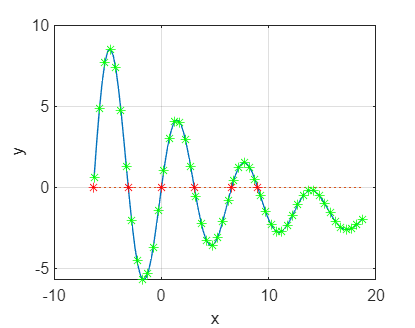

x=linspace(-2*pi,6*pi,100);
f='5*exp(-0.1*x).*sin(x)-0.1*x';
plot(x,eval(f),x,0*x,':');
grid on;
xlabel('x');
ylabel('y');
hold on
for i=-2*pi:0.5:6*pi
    [zr,fr]=fzero(f,i);
    z=5*exp(-0.1*i).*sin(i)-0.1*i;
    plot(zr,fr,'r*',i,z,'*g');
end
hold off;